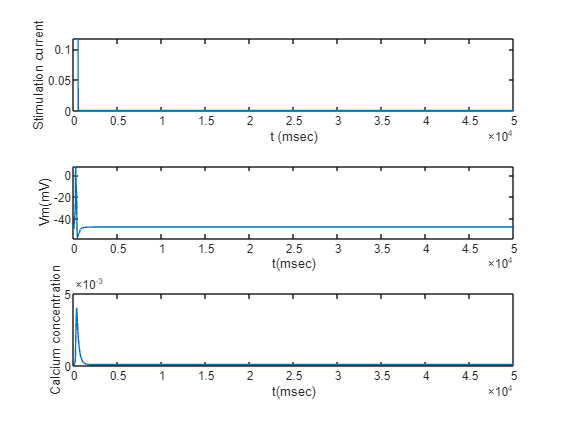

clc; clear all;
t0=0;h=0.5;N=100000;
 
Vm0=-50;nk0=0.079257;Ca0=1e-4;
t(1)=t0;Vm(1)=Vm0;nk(1)=nk0;Ca(1)=Ca0;
%parameters
Istim=zeros(N,1);
for i=1:1000
    Istim(i)=0.1175;
end
 
Gk=0.064; Gkca=0.08; Gl=0.0055; k=0.01;
fc=0.4; alpha=4e-5; Kca=0.01; El=-20;
Ek=-83; Gca=0.02694061; Vca=-20.07451779; Rca=5.97139101;
Jback=0.02397327; T=295; Cae=3; Cm=1;
F=96.487; R=8.314;
 
for n=1:1:N
    Eca=((R*T)/(2*F))*log(Cae/Ca(n));
    hk=1/(1+exp((4.2-Vm(n))/21.1));
    tnk=23.75*exp(-Vm(n)/72.15);
    Ica=Jback+Gca*(Vm(n)-Eca)/(1+exp(-(Vm(n)-Vca)/Rca));
    Ik=Gk*nk(n)*(Vm(n)-Ek);
    Ikca=Gkca*(Vm(n)-Ek)*(Ca(n).^2/(Ca(n).^2+k.^2));
    Il = Gl*(Vm(n) -El);
 
    t(n+1)=t(n)+h;
    Vm(n+1)=Vm(n)+(h*((Istim(n)-Ica-Ik-Ikca-Il)/Cm));
    nk(n+1)=nk(n)+(h*((hk-nk(n))/tnk));
    Ca(n+1)=Ca(n)+(h*(fc*(-alpha*Ica-Kca*Ca(n))));
end
 
%plot
title('Memebrane Potential at Cell level');
subplot(3,1,1);
plot(t(1:100000),Istim');
ylabel('Stimulation current')
xlabel('t (msec)')
subplot(3,1,2)
plot(t,Vm);
ylabel('Vm(mV)');
xlabel('t(msec)');

subplot(3,1,3);
plot(t,Ca);
ylabel('Calcium concentration');
xlabel('t(msec)');

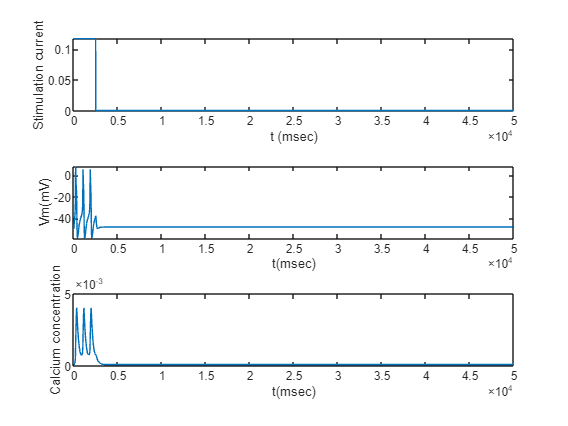

clc; clear all;
t0=0;h=0.5;N=100000;
 Vm0=-50;nk0=0.079257;Ca0=1e-4;
t(1)=t0;Vm(1)=Vm0;nk(1)=nk0;Ca(1)=Ca0;
%parameters
Istim=zeros(N,1);
for i=1:5000
    Istim(i)=0.1175;
end
 
Gk=0.064; Gkca=0.08; Gl=0.0055; k=0.01;
fc=0.4; alpha=4e-5; Kca=0.01; El=-20;
Ek=-83; Gca=0.02694061; Vca=-20.07451779; Rca=5.97139101;
Jback=0.02397327; T=295; Cae=3; Cm=1;
F=96.487; R=8.314;
 
for n=1:1:N
    Eca=((R*T)/(2*F))*log(Cae/Ca(n));
    hk=1/(1+exp((4.2-Vm(n))/21.1));
    tnk=23.75*exp(-Vm(n)/72.15);
    Ica=Jback+Gca*(Vm(n)-Eca)/(1+exp(-(Vm(n)-Vca)/Rca));
    Ik=Gk*nk(n)*(Vm(n)-Ek);
    Ikca=Gkca*(Vm(n)-Ek)*(Ca(n).^2/(Ca(n).^2+k.^2));
    Il = Gl*(Vm(n) -El);
 
    t(n+1)=t(n)+h;
    Vm(n+1)=Vm(n)+(h*((Istim(n)-Ica-Ik-Ikca-Il)/Cm));
    nk(n+1)=nk(n)+(h*((hk-nk(n))/tnk));
    Ca(n+1)=Ca(n)+(h*(fc*(-alpha*Ica-Kca*Ca(n))));
end
 
%plot
title('Memebrane Potential at Cell level');
subplot(3,1,1);
plot(t(1:100000),Istim');
ylabel('Stimulation current')
xlabel('t (msec)')
subplot(3,1,2)
plot(t,Vm);
ylabel('Vm(mV)');
xlabel('t(msec)');

subplot(3,1,3);
plot(t,Ca);
ylabel('Calcium concentration');
xlabel('t(msec)');